%% (L/D)max estimation of similar UAVs

%% AUTHOR = MONISHA VIJAYAN (AE25M037) 
% UAV Names
e=[];
Name = {
    'Yangda Mapird Pro'
    'Yangda Mapird Plus'
    'Yangda Nimbus Pro'
    'Yangda FW-250'
    'Avy Aera'
    'Foxtech Baby Shark 260'
    'P330 Pro'
    'Foxtech AYK-250'
    'Wingcopter 178'
    'FlyDragon FLY-2100'
    'Black Swift S2'
    'Q200'
    'SkyEye Sierra'
    'Foxtech Nimbus'
};
% MTOW (kg)
MTOW = [ ...
    7.5 11.5 8.6 12.0 12.0 13.0 14.0 15.0 ...
    18.0 7.0 9.5 7.0 12.5 6.0 ];
% Wing span(m)
b = [...
    2.1 2.43 1.95 2.5 2.4 2.5 2.53 2.5 ...
    1.78 2.1 3 1.95 2 1.8];
% Wing area (m^2)
Area = [ ...
    0.50 0.65 0.46 0.52 0.96 0.50 0.56 0.50 ...
    0.58 0.52 0.70 0.60 0.30 0.38 ];
% Aspect ratio
AR = [ ...
    8.82 9.08 8.27 12.02 6.00 12.50 11.43 12.50 ...
    5.46 8.48 12.86 6.34 13.33 8.53 ];
% Cruising Altitude (m)
hcruise = [ ...
    3500 3500 3500 3500 3100 3000 5000 2000 ...
    4500 500 4250 4000 3000 1500 ];
% Cruising speed (m/s)
vcruise = [ ...
    17.00 19.44 20.00 23.33 26.39 22 21.00 ...
    25.00 24.00 18.5 18.06 18 20 20];
%Swet/Sref 
sratio =[...
    3.7 3.7 3.7 3.4 2.20 2.3 2.20 2.20...
    3.6 3.7 2.3 3.6 3.6 3.7];
swet=[];
ARwet=[];
for i = 1:length(sratio)
    swt=sratio(i)*Area(i);
    swet(end+1)=swt;
    ARwt=(b(i)^2)/swet(i);
    ARwet(end+1)=ARwt;
end


%Planform type
Planform = {
    'Rectangular'
    'Rectangular'
    'Rectangular'
    'Tapered'
    'Tapered'
    'Tapered'
    'Tapered'
    'Tapered'
    'Rectangular'
    'Rectangular'
    'Tapered'
    'Rectangular'
    'Rectangular'
    'Rectangular'
};

% Taper Ratio
TR=[...
    1 1 1 0.141 0.287 0.119 0.149 0.3103 ...
    1 1 0.636 1 1 1];
%------------------------------------------------------------------------
%Oswald Efficiency Factor
for i = 1:length(MTOW)
    if strcmp(Planform{i},'Rectangular')
        eu(i) = 1.78*(1 - 0.045*AR(i)^0.68) - 0.64;

    elseif strcmp(Planform{i},'Tapered')
        d(i) = (1-TR(i))/(2*(1+TR(i)));
        eu(i) = 1/(1+d(i));
    end
    e(end+1)=eu(i);
end
e = max(e, 0.7);
e = min(e, 1.0);
%disp(e)
%------------------------------------------------------------------------
%ISA Parameters
h = hcruise

h =         3500        3500        3500        3500        3100        3000        5000        2000        4500         500        4250        4000        3000        1500


rho = NaN(size(h));    
T0 = 288.15;             
P0 = 101325;              
rho0 = 1.225;             
L = 0.0065;               
R = 287.05;               
g = 9.80665;              
%------------------------------------------------------------------------
%Density Calculation
for i = 1:length(h)
    if ~isnan(h(i))
        T = T0 - L*h(i);
        rho(i) = rho0*(T/T0)^(g/(R*L) - 1);
    end
end

%disp(rho)
%------------------------------------------------------------------------
%L/D max calculation
L_Dm = [];

for i=1:length(MTOW)
    Cl=(2*MTOW(i)*9.81)/(rho(i)*Area(i)*(vcruise(i)^2));
    L_D=(pi*e(i)*AR(i))/(2*Cl);
    L_Dm(end+1)=L_D;
end
%------------------------------------------------------------------------
%for our UAV
sratio1=3.6;
Sref=0.413;
swet=sratio1*Sref;
ARwsk =4/swet;
disp(sqrt(ARwsk))

    1.6402




%------------------------------------------------------------------------
%[AR_sorted, idx] = sort(sqrt(ARwet));
%L_dm_sorted = L_Dm(idx);
x= linspace(1,4,100);
fit =polyfit(ARwet,L_Dm,1)

fit =     0.8917    9.1957


y=polyval(fit,x)

y =    10.0874   10.1144   10.1415   10.1685   10.1955   10.2225   10.2495   10.2766   10.3036   10.3306   10.3576   10.3847   10.4117   10.4387   10.4657   10.4928   10.5198   10.5468   10.5738   10.6008   10.6279   10.6549   10.6819   10.7089   10.7360   10.7630   10.7900   10.8170   10.8440   10.8711   10.8981   10.9251   10.9521   10.9792   11.0062   11.0332   11.0602   11.0872   11.1143   11.1413   11.1683   11.1953   11.2224   11.2494   11.2764   11.3034   11.3304   11.3575   11.3845   11.4115


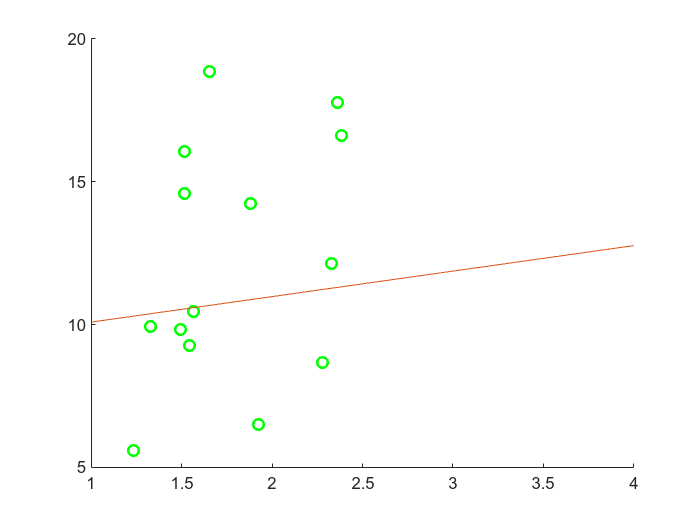

our_L_D_max = polyval(fit,ARwsk)
figure
scatter(sqrt(ARwet),L_Dm,40,"green","o",'LineWidth',1.5)
hold on
plot(x,y)

our_L_D_max = polyval(fit,sqrt(ARwsk))

our_L_D_max = 10.6583

x= linspace(1,3,100);
fit =polyfit(ARwet,L_Dm,1)

fit =     0.8917    9.1957


y=polyval(fit,x)

y =    10.0874   10.1054   10.1234   10.1415   10.1595   10.1775   10.1955   10.2135   10.2315   10.2495   10.2676   10.2856   10.3036   10.3216   10.3396   10.3576   10.3757   10.3937   10.4117   10.4297   10.4477   10.4657   10.4837   10.5018   10.5198   10.5378   10.5558   10.5738   10.5918   10.6098   10.6279   10.6459   10.6639   10.6819   10.6999   10.7179   10.7360   10.7540   10.7720   10.7900   10.8080   10.8260   10.8440   10.8621   10.8801   10.8981   10.9161   10.9341   10.9521   10.9701


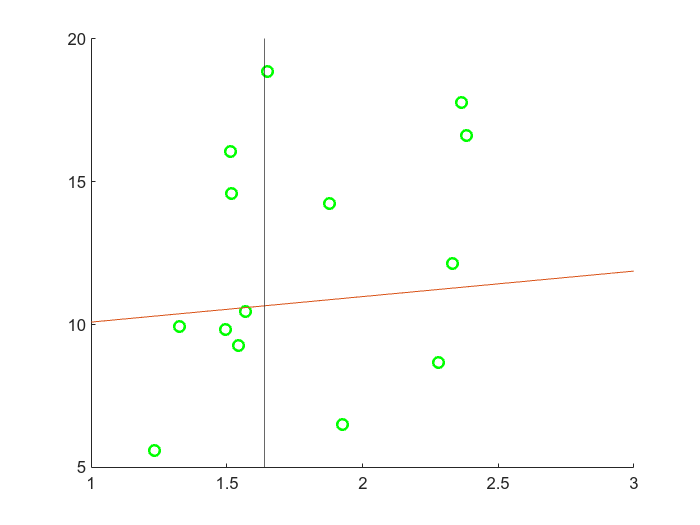


figure
scatter(sqrt(ARwet),L_Dm,40,"green","o",'LineWidth',1.5)
hold on
plot(x,y)
hold on 
xline(sqrt(ARwsk))

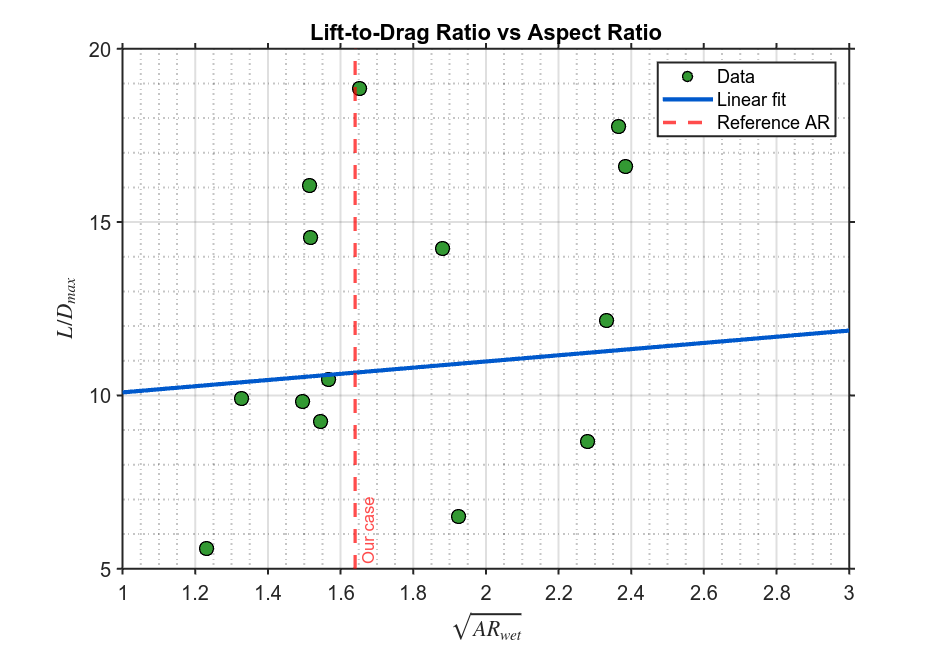

x = linspace(1,3,200);

fit = polyfit(ARwet, L_Dm, 1);
y   = polyval(fit, x);

figure('Color','w','Position',[200 200 800 550])   % white bg + larger figure

% ---- Scatter ----
scatter(sqrt(ARwet), L_Dm, 70, ...
        'filled', ...
        'MarkerFaceColor',[0.2 0.6 0.2], ...
        'MarkerEdgeColor','k', ...
        'LineWidth',0.8)
hold on

% ---- Fit line ----
plot(x, y, ...
     'LineWidth', 2.5, ...
     'Color',[0 0.35 0.8])

% ---- Vertical line ----
xline(sqrt(ARwsk), '--r', ...
      'LineWidth', 2, ...
      'Label','Our case', ...
      'LabelVerticalAlignment','bottom')

% ---- Labels ----
xlabel('$\sqrt{AR_{wet}}$','Interpreter','latex','FontSize',14)
ylabel('$L/D_{max}$','Interpreter','latex','FontSize',14)
title('Lift-to-Drag Ratio vs Aspect Ratio','FontSize',15)

% ---- Grid & styling ----
grid on
grid minor
box on

set(gca, ...
    'FontSize',12, ...
    'LineWidth',1.2, ...
    'TickDir','out')

legend({'Data','Linear fit','Reference AR'}, ...
        'Location','northeast')

 
%%      OPTIMAL SPEED ESTIMATION FOR DIFFERENT PHASES

%Cruise,Max Range,"Minimum Thrust (CDo=CDi�)"
%Climb,Max Angle,"Minimum Thrust (CDo=CDi�)"
%Loiter,Max Time,"Minimum Power (3CDo=CDi�)"
%Descent,Max Glide,"Minimum Thrust (CDo=CDi)"

% ==========================
% AUTHOR = MONISHA VIJAYAN (AE25M037)
%==========================



% BEFORE PAYLOAD DROP
% ==========================
% For our UAV
% ==========================
AR=9.686

AR = 9.6860

MTOW=68.516

MTOW = 68.5160

e=1.78*(1-0.045*AR^0.68)-0.64 %for rectangular wing

e = 0.7648

rho=1.225; % @ cruising altitude = 200m
b=2

b = 2

s=(b^2)/AR

s = 0.4130

vcr=22;
Cl=(2*MTOW)/(rho*vcr^2*s);
k=1/(pi*AR*e)

k = 0.0430

CDo=k*Cl^2

CDo = 0.0135

v0=30; 
L_D_max = 11.595

L_D_max = 11.5950

%% =========================
%  Optimum velocity during CLIMB1  
% ==========================
gamma=8;
Clclimb=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Clclimb(v).^2);
v_optimal_climb=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=(0.5*rho*s*v_optimal_climb^2*2*k*Clclimb(v_optimal_climb)^2);
T_Wcl=(sind(gamma)+(D/MTOW));
T=(T_Wcl*MTOW)

T = 12.7987

Pclimb1=(T*v_optimal_climb)

Pclimb1 = 280.1979

fprintf('Optimum velocity during climb1 = %.3f\n',v_optimal_climb)

Optimum velocity during climb1 = 21.893


fprintf('T/W ratio for climb1 phase = %.3f\n',T_Wcl)

T/W ratio for climb1 phase = 0.187


fprintf('Power required in Climb1 phase = %.3f\n',Pclimb1)

Power required in Climb1 phase = 280.198


%% =========================
%  Optimum velocity during CRUISE1 
% ==========================
gamma=0;
Clcruise=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Clcruise(v).^2);
v_optimal_cruise=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=(0.5*rho*s*v_optimal_cruise^2*2*k*Clcruise(v_optimal_cruise)^2);
T_Wcr=(sind(gamma)+(D/MTOW));
T=(T_Wcr*MTOW)

T = 3.2952

Pcruise1=(T*v_optimal_cruise);
fprintf("Optimum velocity during cruise1 = %.3f\n",v_optimal_cruise)

Optimum velocity during cruise1 = 22.000


fprintf("T/W ratio for cruise1 phase = %.3f\n",T_Wcr)

T/W ratio for cruise1 phase = 0.048


fprintf("Power required in cruise1 phase = %.3f\n",Pcruise1)

Power required in cruise1 phase = 72.494


%% =========================
%  Optimum velocity during DESCENT1 
% ==========================
gamma=-8;
Cldescent=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Cldescent(v).^2);
v_optimal_descent=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=(0.5*rho*s*v_optimal_descent^2*2*k*Cldescent(v_optimal_descent)^2);
T_Wds=abs((sind(gamma)+(D/MTOW)));
T=(T_Wds*MTOW);
Pdescent1=(T*v_optimal_descent);
fprintf("Optimum velocity during descent1 = %.3f\n",v_optimal_descent)

Optimum velocity during descent1 = 21.893


fprintf("T/W ratio for descent1 phase = %.3f\n",T_Wds)

T/W ratio for descent1 phase = 0.092


fprintf("Power required in descent1 phase = %.3f\n",Pdescent1)

Power required in descent1 phase = 137.321



%%==========================
% AFTER PAYLOAD DROP
% ==========================
% For our UAV
% ==========================
MTOW=57.94;
Cl_ref=(2*68.516)/(rho*vcr^2*s);
CDo=k*Cl_ref^2; 
L_Dm=1/(2*sqrt(k*CDo)); 
v0=30; 
%% =========================
%  Optimum velocity during LOITER
% ==========================
gamma=0;
Clloiter=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(3*0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Clloiter(v).^2);
v_optimal_loiter=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=0.5*rho*s*v_optimal_loiter^2*(CDo+k*Clloiter(v_optimal_loiter)^2);
T_Wl=(sind(gamma)+(D/MTOW));
T=(T_Wl*MTOW);
Ploiter=(T*v_optimal_loiter);
fprintf("Optimum velocity during loiter = %.3f\n",v_optimal_loiter)

Optimum velocity during loiter = 15.372


fprintf("T/W ratio for loiter phase = %.3f\n",T_Wl)

T/W ratio for loiter phase = 0.056


fprintf("Power required in loiter phase = %.3f\n",Ploiter)

Power required in loiter phase = 49.462


%% =========================
%  Optimum velocity during CLIMB2
% ==========================
gamma=8;
Clclimb=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Clclimb(v).^2);
v_optimal_climb=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=0.5*rho*s*v_optimal_climb^2*2*CDo;
T_Wcl=(sind(gamma)+(D/MTOW));
T=(T_Wcl*MTOW);
Pclimb2=(T*v_optimal_climb);
fprintf("Optimum velocity during climb2 = %.3f\n",v_optimal_climb)

Optimum velocity during climb2 = 20.132


fprintf("T/W ratio for climb2 phase = %.3f\n",T_Wcl)

T/W ratio for climb2 phase = 0.187


fprintf("Power required in Climb2 phase = %.3f\n",Pclimb2)

Power required in Climb2 phase = 217.894


%% =========================
%  Optimum velocity during CRUISE2
% ==========================
gamma=0;
Clcruise=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Clcruise(v).^2);
v_optimal_cruise=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=0.5*rho*s*v_optimal_cruise^2*2*CDo;
T_Wcr=(sind(gamma)+(D/MTOW));
T=(T_Wcr*MTOW)

T = 2.7865

Pcruise2=(T*v_optimal_cruise);
fprintf("Optimum velocity during cruise2 = %.3f\n",v_optimal_cruise)

Optimum velocity during cruise2 = 20.231


fprintf("T/W ratio for cruise2 phase = %.3f\n",T_Wcr)

T/W ratio for cruise2 phase = 0.048


fprintf("Power required in cruise2 phase = %.3f\n",Pcruise2)

Power required in cruise2 phase = 56.374


%% =========================
%  Optimum velocity during DESCENT2
% ==========================
gamma=-8;
Cldescent=@(v)(2*MTOW*cosd(gamma))/(rho*s*v.^2);
fun=@(v)(0.5*rho*s*v.^2*CDo)-(0.5*rho*s*v.^2.*k.*Cldescent(v).^2);
v_optimal_descent=fsolve(fun,v0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


D=0.5*rho*s*v_optimal_descent^2*2*CDo;
T_Wds=abs((sind(gamma)+(D/MTOW)));
T=(T_Wds*MTOW)

T = 5.3043

Pdescent2=(T*v_optimal_descent);
fprintf("Optimum velocity during descent2 = %.3f\n",v_optimal_descent)

Optimum velocity during descent2 = 20.132


fprintf("T/W ratio for descent2 phase = %.3f\n",T_Wds)

T/W ratio for descent2 phase = 0.092


fprintf("Power required in descent2 phase = %.3f\n",Pdescent2)

Power required in descent2 phase = 106.787


% climb_1
AR=9.686;
MTOW=68.516;
e=1.78*(1-0.045*AR^0.68)-0.64; %for rectangular wing
rho=1.225; % @ cruising altitude = 200m
b=2;
s=(b^2)/AR

s = 0.4130

vcr=22;
Cl=(2*MTOW)/(rho*vcr^2*s);
k=1/(pi*AR*e)

k = 0.0430

CDo=k*Cl^2

CDo = 0.0135

v0=30; 
L_D_max = 11.595

L_D_max = 11.5950

gamma = 8

gamma = 8

Lift = MTOW*cosd(gamma)

Lift = 67.8492

Drag = Lift/L_D_max

Drag = 5.8516

thrust_required_climb = Drag + MTOW*sind(gamma)

thrust_required_climb = 15.3872

C_L_climb = @(v) Lift/(0.5*rho*s*v^2)

C_L_climb = function_handle with value:
    @(v)Lift/(0.5*rho*s*v^2)


C_d_i_climb_func = @(v) C_L_climb(v)^2/(pi*e*AR)

C_d_i_climb_func = function_handle with value:
    @(v)C_L_climb(v)^2/(pi*e*AR)


Drag_function = @(v)(0.5*rho*s*v^2*(CDo + C_d_i_climb_func(v))) - Drag

Drag_function = function_handle with value:
    @(v)(0.5*rho*s*v^2*(CDo+C_d_i_climb_func(v)))-Drag


optimal_velocity_climb = fsolve(Drag_function,v0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


optimal_velocity_climb = 39.6602

Power_required_climb = thrust_required_climb*optimal_velocity_climb

Power_required_climb = 610.2587

P_W_climb = Power_required_climb/MTOW

P_W_climb = 8.9068

% criuise_1
Lift_cruise = 